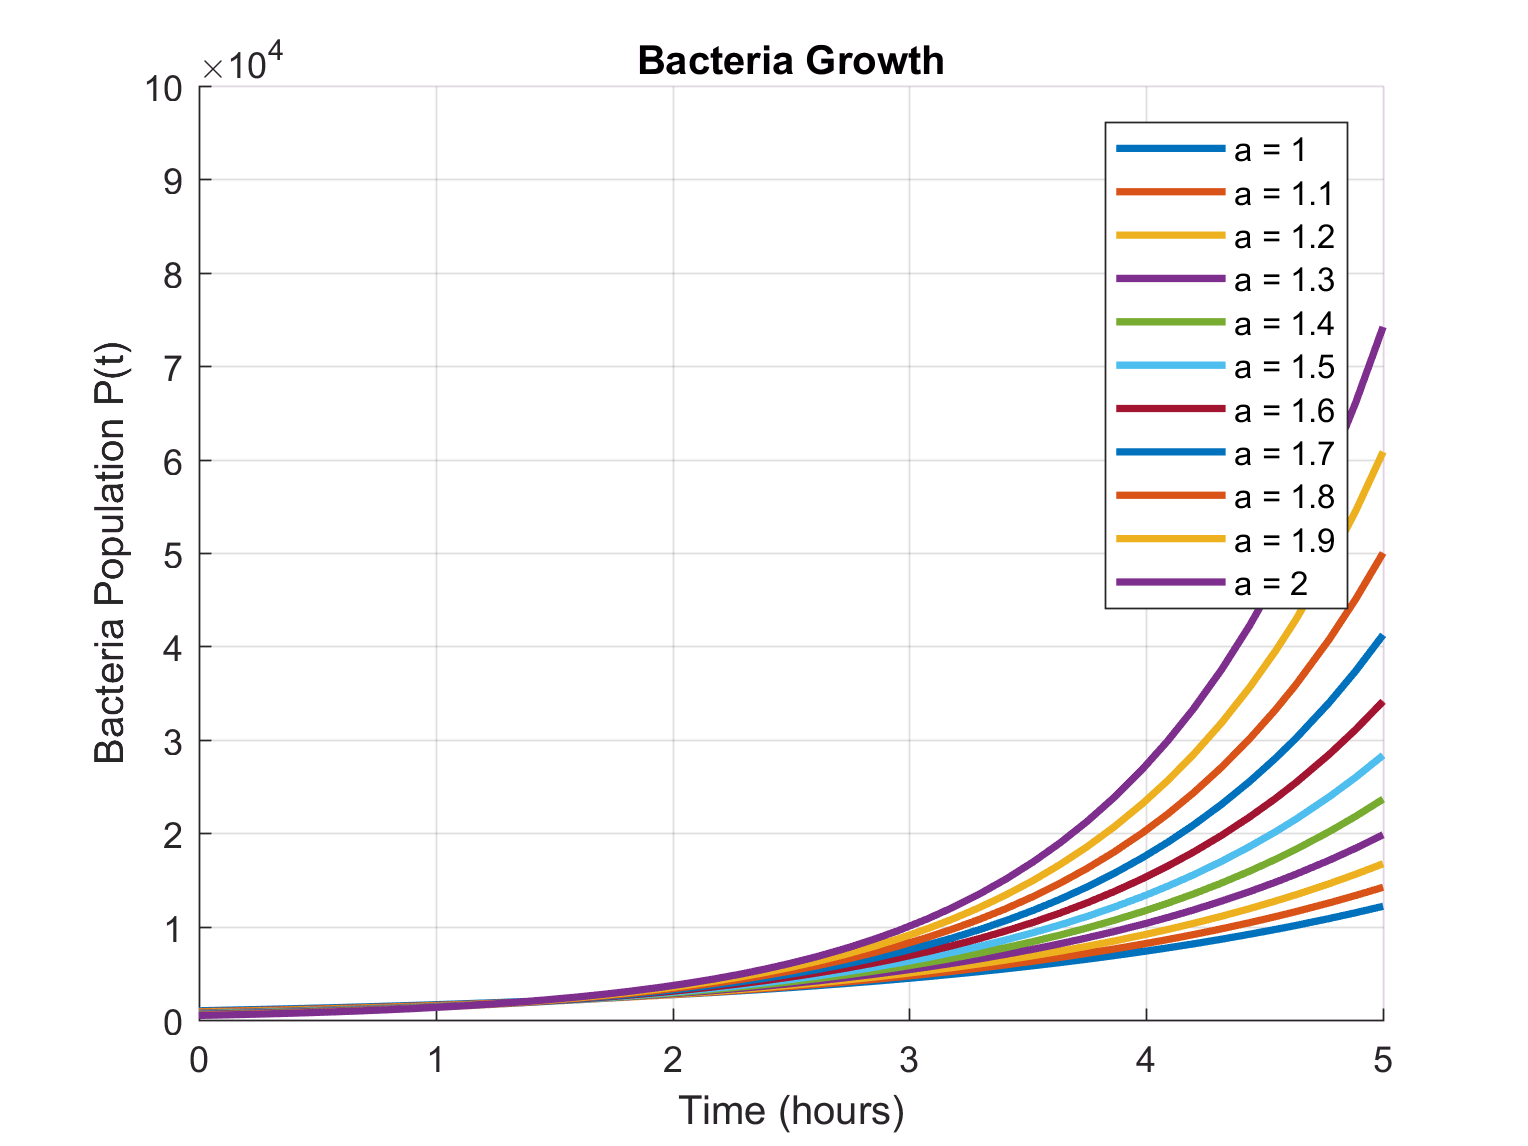

%Bacteria Growth and Interpretation (SUBMISSION)
close all; clear all;

% define variable and function with looping a value
syms t;
legendInfo = [];
hold on;
for a = 1.0:0.1:2.0
    P(t) = (1000/a)*exp(0.5*a*t);
    fplot(P(t), 'LineWidth', 2);
    legendInfo{(10*a)-9} = ['a = ' num2str(a)];
end

% labelling of graph
grid on;
axis([0 5 0 10*10^4]);
title('Bacteria Growth');
xlabel('Time (hours)');
ylabel('Bacteria Population P(t)');
legend(legendInfo);
hold off;


%ANSWERS
%1) Order listed in legend; the greater the "a" value, the faster the curve grows.
%2) The population with a=2.0 grows the fastest without bound. Thus, there are no values of t which the populaiton will reach the its maximum. t~=1.386 s where a=2.0 will become the biggest population.
%3) a=1.0 DB=~1.5 hours ; a=1.5 DB=~1 hour ; a=2.0 DB=~0.65 hour; Relationship between the doubling time and a value: t(double) = (2*ln(2))/(a)
%4) The similarities in doing matrix math by-hand versus via MATLAB is that the concepts and answers are identical. The difference would be the procedure and the time it takes to compute the answer, with MATLAB being much faster. Thus, it is more appropriate to calculate matrix operations on MATLAB if the numbers involved are complex and if the matrix carries a big size.
%   Some important considerations an engineer should think about when using “for” loops would be the number of times the loops should be run and the prevention of accidentally running the loop forever.
